# Contest Report

% Read in the list of all solvers
solvers = readtimetable("allSolvers.csv");

% Get rid of bad entries
% The score may be infinite or negative. Neither is a good state.
ix = isinf(solvers.score)|(solvers.result<0);
solvers(ix,:) = [];

Here is the list of all the solvers

solvers

solvers = 1x5 timetable
             t              result    computeTime    score      author                         commit                   
    ____________________    ______    ___________    _____    __________    ____________________________________________

    06-May-2024 21:52:36    26.017      0.34412      164.5    {'gulley'}    {'c51b2fcf7b51ebe382d55723d14c15474980b116'}


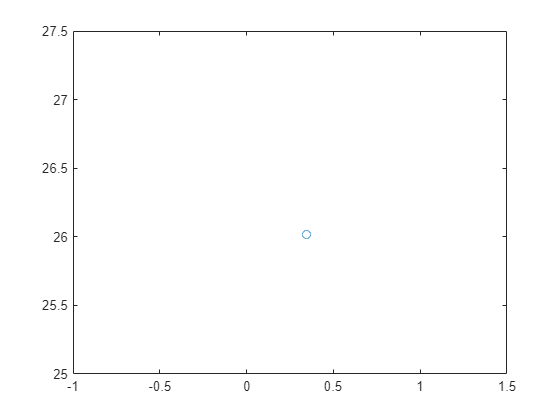

plot(solvers.computeTime,solvers.result,"-o")

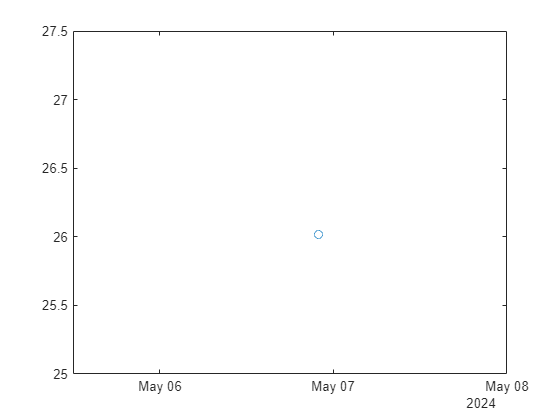

plot(solvers.t,solvers.result,"-o")